# LLENTAB - Prefabricated steel hall

clc;clear all;clearvars;uqlab;close all; addpath 'Functions\'

Copyright 2013-2024, Stefano Marelli and Bruno Sudret.
This is UQLab, version 2.1
UQLab is distributed under the BSD 3-clause open source license available at: 
<a href="https://uqlab.com/license">https://uqlab.com/license</a>.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information



## Vazník - Dolní pás

Section properties

section.h_w =  119.0   * 10^-3; % m
section.b   =  110.0   * 10^-3; % m
section.c   =   42.0   * 10^-3; % m
section.e_1 =   55.8   * 10^-3; % m
section.A_s = 1615.93  * 10^-6; % m^2
section.t   =    4.0   * 10^-3; % m
section.n_cross = 2           ; % ea
section.d_0 = 12.5 * 10^-3    ; % m
section.X = 1                 ;
section.A_net = section.A_s - section.t * (section.n_cross * section.d_0 * 2 / section.X);
section.A_ratio = section.A_net / section.A_s;


% Material properties
section.f_u =   480.0  * 10^3 ; % kN/m
section.f_y =   420.0  * 10^3  ; % kN/m

% Internal forces - characteristic values
snow.s_kg = 70; % mm/m2
snow.s_k = snow.s_kg;
snow.s_kd = snow.s_k*0.8;

wind.v_b_0 = 25 ; %m/s
wind.q_b = 0.39 ; %kN/m2


forces.G_s.N_k = 100.28 ; %kN
forces.G_p.N_k = 61.60 ; %kN
forces.Q.N_k = 140.47 ; %kN

snow.ratio = forces.Q.N_k / snow.s_kd; % taken from static report
forces.Q.N_k = snow.ratio * snow.s_kd; 
fprintf ('Internal forces:\n'); fprintf ('    Self weight: %.3f kN\n',forces.G_s.N_k); fprintf ('    Pernament load: %.3f kN\n',forces.G_p.N_k); fprintf ('    Snow load: %.3f kN\n',forces.Q.N_k); fprintf ('    Snow to internal forces ratio: %.3f',snow.ratio);

Internal forces:
    Self weight: 100.280 kN
    Pernament load: 61.600 kN
    Snow load: 140.470 kN
    Snow to internal forces ratio: 2.508

## Eurocode analysis


$$E_d = \gamma_g \cdot G + \gamma_q \cdot Q \\
R_d = \min \left( \frac{A_s \cdot f_y}{\gamma_{M0}} ; \frac{A_{net}  \cdot f_u}{\gamma_{M2}} \right)$$


EN.gamma_q = 1.50 ;
EN.gamma_g = 1.35 ;
EN.gamma_M0 = 1.00 ;
EN.gamma_M2 = 1.25 ;
EN.E_d = (forces.G_s.N_k + forces.G_p.N_k) * EN.gamma_g + forces.Q.N_k * EN.gamma_q; % kN
EN.R_d_l = section.A_s * section.f_y / EN.gamma_M0;
EN.R_d_net = section.A_net * section.f_u / EN.gamma_M2;
EN.R_d = min(EN.R_d_net,EN.R_d_l);  % CHECK
EN.ration = EN.E_d / EN.R_d;
EN.A_s_en = EN.E_d / section.f_y * EN.gamma_M0; %m^2

## Probabilistic reliability analysis

% Probablistic models of variables
inputOpts = defineProbabilisticModels(section, forces, snow);

#### Real snow data from Ruzyne

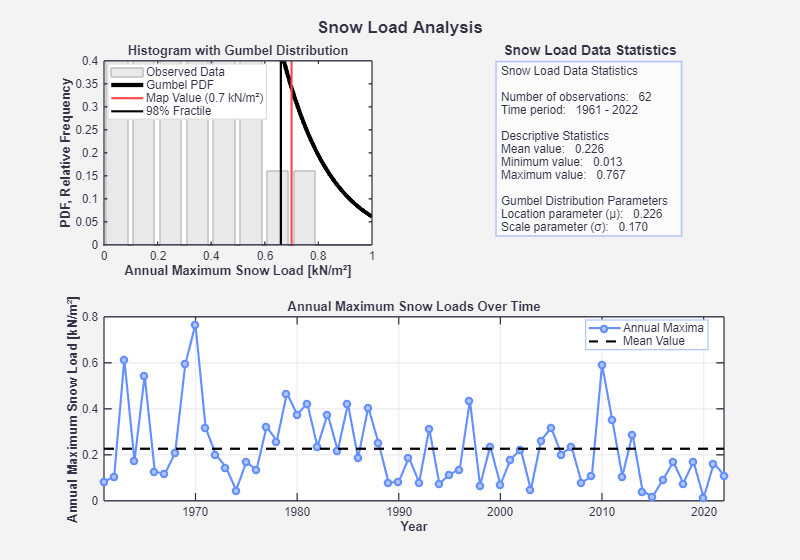

Plots were saved to: Plots\snowData


% 1. Načtení dat
data = readtable('data_Ruzyne.csv');
roky = data.Var1; % první sloupec obsahuje roky
rocni_maxima = data.Var2/100; % druhý sloupec obsahuje maxima

% 2. Fitnutí Gumbelova rozdělení (Extreme Value Type I)
pd = fitdist(rocni_maxima, 'ExtremeValue');

mu = mean(rocni_maxima);       % location parametr (μ)
sigma = 0.17; % scale parametr (β)

% 3. Výpočet kvantilů
charakteristicka_hodnota = icdf(pd, 0.98);  % 98% fraktil1
mean_val = mean(rocni_maxima);
stdev_ratio = std(rocni_maxima) / mean_val;
skew_val = skewness(rocni_maxima);

% 5. Výpočet statistických parametrů pro kontrolu
pocet_mereni = length(rocni_maxima);
prumer = mean(rocni_maxima);
smerodatna_odchylka = std(rocni_maxima);
variacni_koeficient = smerodatna_odchylka / prumer;
sikmost = skewness(rocni_maxima);
min_hodnota = min(rocni_maxima);
max_hodnota = max(rocni_maxima);
% 4. Vytvoření proměnné pro UQ lab bez použití createUQVariable funkce
% Definujte přímo strukturu proměnné podle UQ lab požadavků
inputOpts.Marginals(10).Type = 'Gumbel';
inputOpts.Marginals(10).Parameters = [mu, sigma]; % [location, scale]
inputOpts.Marginals(10).Name = 'Sg'; % jméno proměnné

% 5. Vizualizace nafitování dat
snowDataPlot(roky, rocni_maxima, mu, sigma, 'Plots/snowData');

% visualize_snow_load_data(rocni_maxima, roky, pd)

input = uq_createInput(inputOpts);

## Limit State Function - snow data


$$g(x) = \theta _R \cdot \min \left(R_u;R_y) - \theta _E \cdot (G + s_{gk} \cdot C_0 \cdot s_{ratio})$$


N = 10^7; % počet simulací
ModelOpts.mFile = 'limitStateSnowDataFunction';
ModelOpts.isVectorized = true;

% Vytvoření modelu
myModel = uq_createModel(ModelOpts);
% Nastavení analýzy spolehlivosti metodou FORM
SimOpts.FORM.ComputeSensitivity = true;  % Explicitní příkaz k výpočtu citlivostních indexů
SimOpts.Type = 'Reliability';
SimOpts.Method = 'FORM';  % Změna na FORM metodu
SimOpts.FORM.Search = 'StrongJoint';  % Výběr algoritmu hledání designového bodu
SimOpts.FORM.MaxIterations = 100;  % Maximální počet iterací
SimOpts.FORM.Tolerance = 1e-6;  % Toleranční kritérium konvergence

% Vytvoření a spuštění analýzy
reliability = uq_createAnalysis(SimOpts);


Starting FORM Analysis...

FORM: Finished.


### Reliability Analysis Visualization

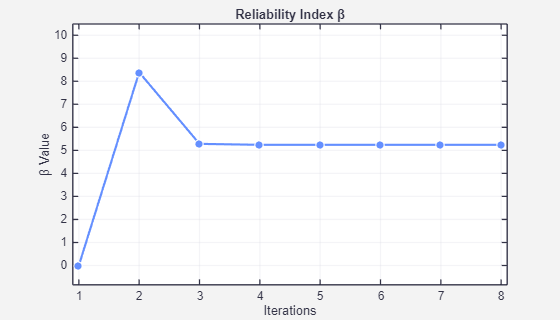

Graf "reliability_index" byl uložen do: Plots\RA_snowData\reliability_index


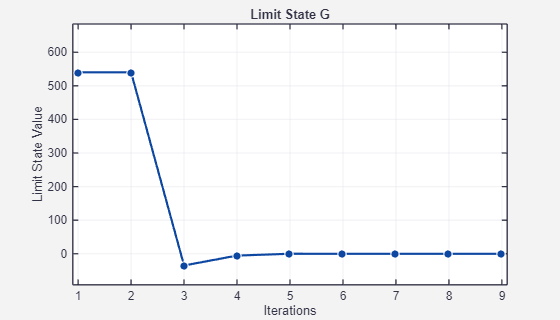

Graf "limit_state" byl uložen do: Plots\RA_snowData\limit_state


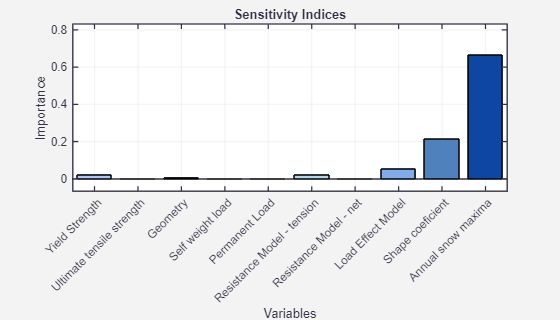

Graf "sensitivity_indices" byl uložen do: Plots\RA_snowData\sensitivity_indices


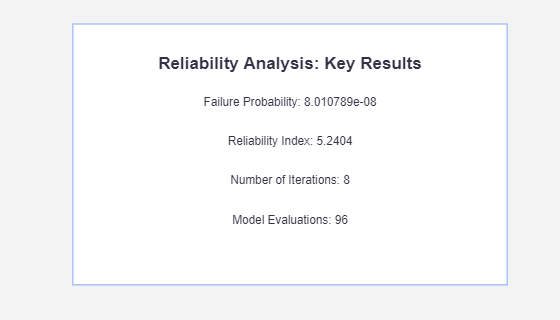

Graf "key_results" byl uložen do: Plots\RA_snowData\key_results
Všechny grafy byly úspěšně vykresleny.



% Save graph
if ~exist('Plots', 'dir')
   mkdir('Plots')
end

% Použití s exportem (zobrazení a uložení grafů)
 plotReliabilityForPoster(reliability,'Plots/RA_snowData',{'Yield Strength','Ultimate tensile strength', 'Geometry', 'Self weight load','Permanent Load', 'Resistance Model - tension','Resistance Model - net', 'Load Effect Model','Shape coeficient','Annual snow maxima'});

if false
Print key numerical results
fprintf('\nKey Reliability Analysis Results:\n');
fprintf('Failure Probability: %e\n', results.Pf);
fprintf('Reliability Index: %.4f\n', results.BetaHL);
fprintf('Number of Iterations: %d\n', results.Iterations);
fprintf('Number of Model Evaluations: %d\n', results.ModelEvaluations);

% Interpretation of results
fprintf('\nResults Interpretation:\n');
fprintf('- Extremely low failure probability (%.2e)\n', results.Pf);
fprintf('- High reliability index (%.4f)\n', results.BetaHL);
fprintf('- Convergence achieved in %d iterations\n', results.Iterations);
end

## Comparison of Probabilistic and Eurocode Safety Levels

%% Reliability Analysis vs. Cross-Sectional Area Ratio
% This section analyzes how reliability index (beta) and resistance-to-load ratio (R_d/E_d) 
% change based on the ratio of actual cross-sectional area (A_g) to Eurocode required area (A_s_EN)

displayOriginalValues(section,EN);


Original cross-sectional area values:
Original section area (A_s): 0.001616 m² (1615.93 mm²)
Eurocode required area (A_s_EN): 0.001022 m² (1022.01 mm²)
Original ratio (A_s/A_s_EN): 1.5811



% Define the range of ratios A_g/A_s_EN to analyze
ratio_range = linspace(0.5, 2.0, 50);  % Ratio from 0.5 to 2.0 times A_s_EN
beta_values = zeros(size(ratio_range));
rd_ed_ratio = zeros(size(ratio_range));

% Store original section area for reference
original_area = section.A_s;
original_EN_area = EN.A_s_en;
original_ratio = original_area / original_EN_area;
ModelOpts.mFile = 'limitState_Ry';
ModelOpts.isVectorized = true;

% Vytvoření modelu
myModel = uq_createModel(ModelOpts);

% Loop through each ratio value
for i = 1:length(ratio_range)
    % Calculate new section area based on the ratio
    section.A_s = original_EN_area * ratio_range(i);
    
    % Update the geometry variable in the probabilistic model
    model.a_s.V_x = 3 / 100; % percent
    model.a_s.ratio = 1.00 ;
    model.a_s.Dist = 'Gaussian';
    model.a_s.nominal = section.A_s;
    model.a_s.variable = createUQVariable(model.a_s, 'As');
    inputOpts.Marginals(3) = model.a_s.variable;
    
    % Update input object
    input = uq_createInput(inputOpts);
    
    % Run reliability analysis
    reliability = uq_createAnalysis(SimOpts);
    
    % Store the reliability index for this ratio
    beta_values_ry(i) = reliability.Results.BetaHL;
    
    % Calculate and store R_d/E_d ratio
    EN.R_d = section.A_s * section.f_y / EN.gamma_M0;
    rd_ed_ratio(i) = EN.R_d / EN.E_d;
end


Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM

ModelOpts.mFile = 'limitState_Ru';
ModelOpts.isVectorized = true;

% Vytvoření modelu
myModel = uq_createModel(ModelOpts);
% Loop through each ratio value
for i = 1:length(ratio_range)
    % Calculate new section area based on the ratio
    section.A_s = original_EN_area * ratio_range(i);
    
    % Update the geometry variable in the probabilistic model
    model.a_s.V_x = 3 / 100; % percent
    model.a_s.ratio = 1.00 ;
    model.a_s.Dist = 'Gaussian';
    model.a_s.nominal = section.A_s;
    model.a_s.variable = createUQVariable(model.a_s, 'As');
    inputOpts.Marginals(3) = model.a_s.variable;
    
    % Update input object
    input = uq_createInput(inputOpts);
    
    % Run reliability analysis
    reliability = uq_createAnalysis(SimOpts);
    
    % Store the reliability index for this ratio
    beta_values_ru(i) = reliability.Results.BetaHL;
end


Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM: Finished.

Starting FORM Analysis...

FORM


% Reset section area to original value after analysis
section.A_s = original_area;

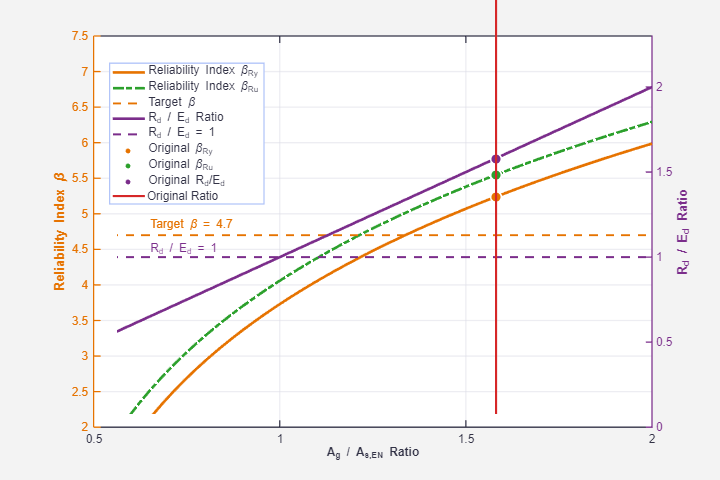

Graf byl uložen do: Plots\reliability_analysis

Safety at original cross-section area:
   Reliability index (β_Ry) at original area: 5.2403
   Reliability index (β_Ru) at original area: 5.5486
   R_d/E_d ratio at original area: 1.5811

Minimum A_g/A_s,EN ratio needed to achieve target reliability (β = 4.7):
   For β_Ry: 1.327
   For β_Ru: 1.204
Minimum A_g/A_s,EN ratio needed for R_d/E_d ≥ 1: 0.990


%Plots
plotReliabilityVsAreaRatio(ratio_range, beta_values_ry, beta_values_ru, rd_ed_ratio, original_ratio, 'Plots/reliability_analysis');